# **Impedance Model**

## Second order model representation

If we consider that a simple mass $M$, damper $B$, spring $K$, system is to be able to model the impedance behaviour of the human arm along an axis $\overrightarrow{x}$, while interacting with an environment then, we can write:

$\left({\textrm{Ms}}^2 +\textrm{Bs}+K\right)X_e \left(p\right)=F_e \left(p\right)$,

with$X$ the endpoint position of the arm, and $F$ the force of the arm on the environment, both along $\overrightarrow{x}$.

clear all
syms M D K;
syms xe fe;

The state representation of the system is:

$\dot{\mathit{\mathbf{X}}} \left(t\right)=\textrm{AX}\left(t\right)+\textrm{Bu}\left(t\right)$,


$$y\left(t\right)=\textrm{CX}\left(t\right)$$


$\mathit{\mathbf{X}}\left(t\right)=\left\lbrack \begin{array}{c}
x_e \left(t\right)\\
\dot{x_e } \left(t\right)
\end{array}\right\rbrack$, $u\left(t\right)=f_e \left(t\right)$

A = [  0 ,   1 ;
     -K/M, -D/M]

$$A = \left(\begin{array}{cc} 0 & 1\\ -\frac{K}{M} & -\frac{\text{D}}{M} \end{array}\right)$$

B = [0; 1/M]

$$B = \left(\begin{array}{c} 0\\ \frac{1}{M} \end{array}\right)$$

C = [1, 0] % or C = [0, 1] if the velocity is considered as output

C =      1     0


## Discretization

Assuming that the discretization is made through a zero order hold, and a sampling period $T$:


$$\mathit{\mathbf{X}}\left\lbrack k+1\right\rbrack ={\mathit{\mathbf{A}}}_d \mathit{\mathbf{X}}\left\lbrack k\right\rbrack +{\mathit{\mathbf{B}}}_d \;u\left\lbrack k\right\rbrack$$



$${\mathit{\mathbf{A}}}_d =e^{\mathit{\mathbf{A}}\;T} ,$$



$${\mathit{\mathbf{B}}}_d =\left(\int_{\tau =0}^T e^{\mathit{\mathbf{A}}\tau \;} d\tau \;\right)\mathit{\mathbf{B}}={\mathit{\mathbf{A}}}^{-1} \left({\mathit{\mathbf{A}}}_d -\mathit{\mathbf{I}}\right)\mathit{\mathbf{B}},\exists \;{\mathit{\mathbf{A}}}^{-1}$$


T = 1e-3; % 1ms
Ad = expm(A*T);
Bd = A\(Ad - eye(2))*B; % if A is not a singular matrix
Cd = C;

We can now express $x_e$:


$$x_e \left\lbrack k\right\rbrack =\left\lbrack a_1 ,a_2 \right\rbrack \left\lbrack \begin{array}{c}
x_e \left\lbrack k-1\right\rbrack \\
x_e \left\lbrack k-2\right\rbrack 
\end{array}\right\rbrack +{b_2 \;\;f}_e \left\lbrack k-2\right\rbrack$$


with:


$$a_1 ={\mathit{\mathbf{A}}}_d \left(2,1\right),a_2 ={\mathit{\mathbf{A}}}_d \left(2,2\right),b_2 ={\mathit{\mathbf{B}}}_d \left(2\right)$$


a1 = Ad(2,1);
a2 = Ad(2,2);
b2 = Bd(2);

## Identification

The parameters $a_1 ,a_2 ,b_{2\;}$ can be estimated using identification methodologies, with real dataset from human robot physical interactions.

### Data generation

load 'data_2020_Nov_17/data_without_impacts_2020_11_17.mat' 't' 'thetas' 'forces_unf'
addpath('utils') % 
addpath('../../force_torque_sensor') % for force pre-processing

The data from the experiment is preprocessed to obtain a real shaped signal of the interaction force, that the robots applies on the environment $f_{r\to e\;}$.

exp_nb = randi([0 15],1,1); % chose a random experimental dataset
t = t{exp_nb} - t{exp_nb}(1); % t0 = 0s
% from sensor base to robot base
f_tmp = forces_filtering(forces_unf{exp_nb}', forces_unf{exp_nb}', thetas{exp_nb}', t);
%
dt = 1e-3; % sampling
[b,a] = butter(2,50/(1/(2*dt)),'low'); % BW 2nd order low pass filter (cutoff freq. 50 Hz)
f_tmp = -f_tmp(3,:)'; % fz conversion from f(e->r) to f(r->e), robot force on the environment
f = -filtfilt(b,a,f_tmp); % zero phase digital filtering
clear forces_unf thetas f_tmp % clear unecessary data

This real input in then injected in a simulated system with known impedance parameters:

input_force.signals.values = f;
input_force.time = t;
% impedance parameters
M = 0.2;
B = 10;
K = 200;
% perturbation introduced in simulation
ext_signal = 1;
pert_mag = 2;
pert_space = ceil(3.3/dt); % samples
pert_duration = 0.060/dt;  % samples
t_max = t(end);
out = sim('Impedance_env_simulation/KBM_sim',t_max);

The results from the simulation are collected:

fz = out.force.data;
z = out.position.data;
t = out.force.Time;
% get the rising edges indexes of the perturbations
pert_idx = find(diff(out.perturbations.data) > 0)';
pert_val = pert_mag.*ones(size(pert_idx));

The data is then processed to extract the differential force and position trajectories between the virtual and the actual trajectories:

% PARAMETERS
idx_wndw_virt_traj   = ceil(0.200/dt); % 200ms (position)
idx_wndw_virt_f_traj = ceil(0.065/dt); % 65ms  (force) 
idx_wndw_imp_eval    = ceil(0.200/dt); % 200ms       
idx_delay            = ceil(0.000/dt); % 0ms
idx_window = max(idx_wndw_imp_eval, idx_wndw_virt_traj);
nb_param = 3; % K B M

% DATA PRE-PROCESSING
delta_z = DIFF_TRAJECT(idx_window, idx_wndw_virt_traj, z, t, pert_idx, pert_val, idx_delay);
delta_fz = DIFF_TRAJECT(idx_window, idx_wndw_virt_f_traj, fz, t, pert_idx, pert_val, idx_delay);

delta_z.computeDiffTraject('VirtTrajMethod', 'spline');
delta_fz.computeDiffTraject('VirtTrajMethod', 'filterPlus');
delta_z.computeDerivatives();

The methodology can be compared to the real virtual trajectories:

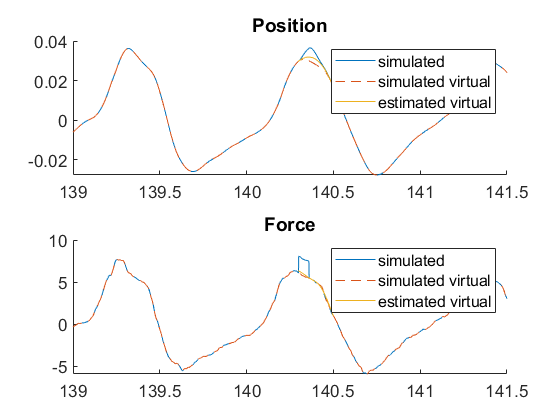

% real virtual trajectories
fz0 = out.virt_force.data;
z0 = out.virt_position.data;
%
figure('DefaultAxesFontSize',14)
subplot(2,1,1)
title('Position')
hold on
plot(t,z)
plot(t,z0, '--')
plot(delta_z.t_traject, delta_z.virt_traject, 'Color', [0.9290, 0.6940, 0.1250])
xlim([139 141.5])
legend('simulated', 'simulated virtual', 'estimated virtual')
subplot(2,1,2)
title('Force')
hold on
plot(t,fz)
plot(t,fz0, '--')
plot(delta_fz.t_traject, delta_fz.virt_traject, 'Color', [0.9290, 0.6940, 0.1250])
xlim([139 141.5])
legend('simulated', 'simulated virtual', 'estimated virtual')

### Discrete time identification algorithms

text text text

%code code ...